clc
clear

imgPath = 'imgs/landscape.jpg';
% imgPath = 'imgs/tivoli.jpg';
% imgPath = 'imgs/tivoli2.jpeg';
% imgPath = 'imgs/mountain_low_res.png';
% imgPath = 'imgs/mountains_2.jpg';
% imgPath = 'imgs/landscape_mountain.jpg';


## Image preprocessing

minW = 600;        % Min input width (px)
maxW = 3000;       % Max input width (px)
Wout = 1200;       % Output width (px)

img = im2double(imread(imgPath));
[height, width] = size(img);
fprintf("Original size: %d x %d", width, height)

Original size: 1650 x 367

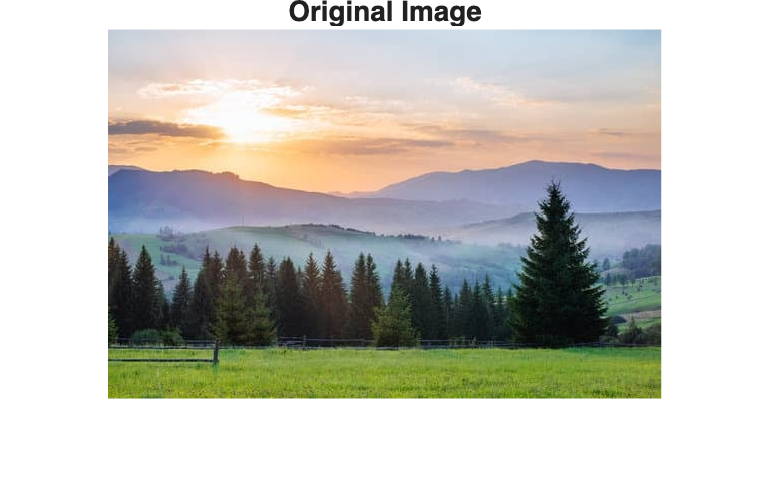

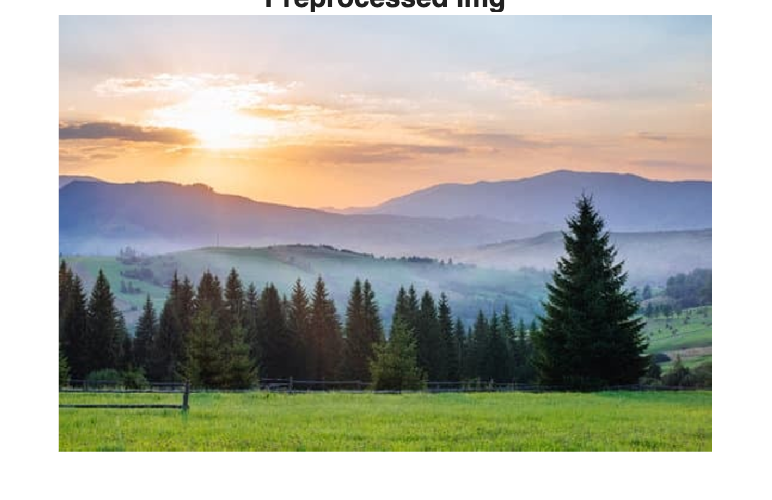

processedImg = preprocessImage(img, minW, maxW, Wout);

Ilab = rgb2lab(processedImg);


## Color palette generation & palette optimization

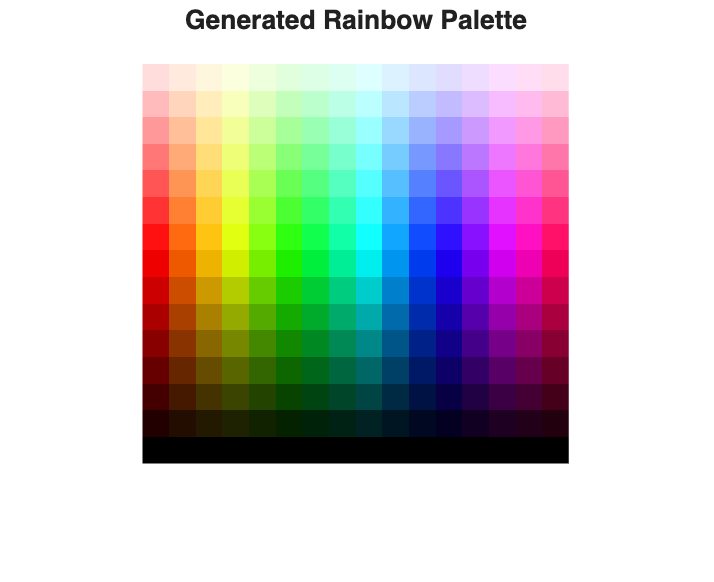

numColors= 16;              % Number of base colors
numShades = 16;             % Number of shades of the base colors

sampleQuantity = 50000;      % Number of samples for the optimized palette
numOptimizedColors = 500;     % Number of colors in the optimized palette

[fullPaletteLab, paletteImage] = make_rainbow_palette(numColors, numShades);

figure;
imshow(imresize(paletteImage, 20, 'nearest')); 
title('Generated Rainbow Palette');

fprintf('Generated Palette (%d colors)', numColors * numShades)

Generated Palette (256 colors)

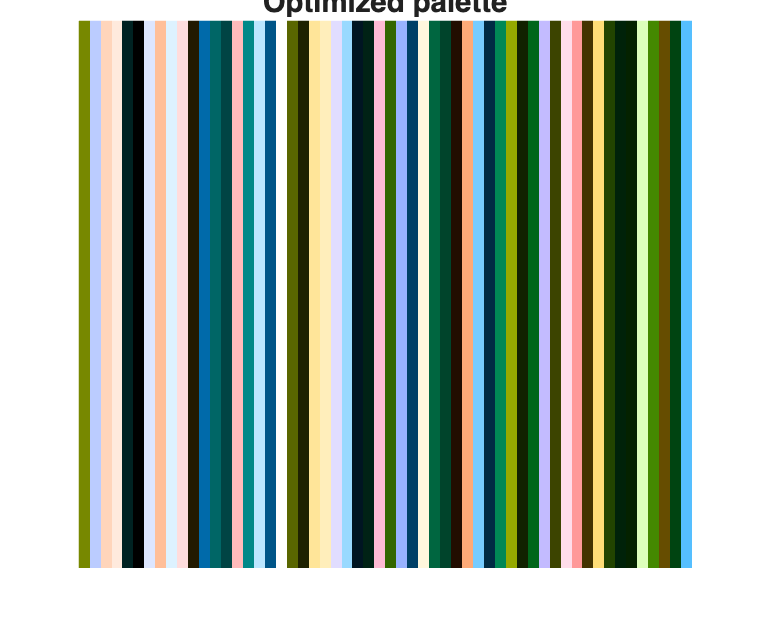


[optimizedPaletteLab, optPaletteSwatch] = optimize_palette(Ilab, fullPaletteLab, numOptimizedColors, sampleQuantity);

figure;
imshow(imresize(optPaletteSwatch, 15, "nearest"));
title("Optimized palette");

fprintf('Optimized Palette (%d colors chosen from %d)', numOptimizedColors, numColors * numShades)

Optimized Palette (500 colors chosen from 256)

## Image reconstruction

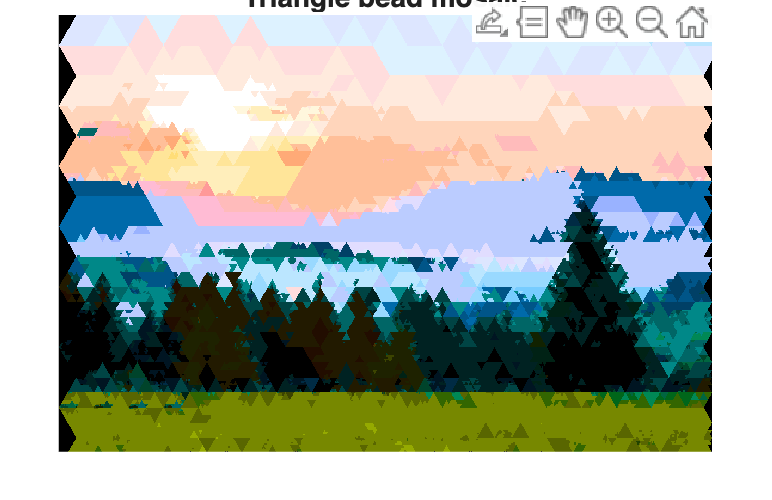

maxSize = 64;              % Largest triangle size (px)
minSize = 2;               % Smallest triangle size (px)
detailThreshold = 10;      % How much brightness variation triggers a split

[mosaicRGB, idxMap] = reproduce_adaptive_triangle(Ilab, optimizedPaletteLab, maxSize, minSize, detailThreshold);

figure;
imshow(mosaicRGB);
axis image off;
title('Triangle bead mosaic');

fprintf("Largest triangles: %d and smallest triangles: %d", maxSize, minSize)

Largest triangles: 64 and smallest triangles: 2

## Evaluation

[ssim_score, psnr_score, scielab_score] = evaluate_quality(processedImg, mosaicRGB);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...



fprintf('--- Quality Metrics ---\n');

--- Quality Metrics ---


fprintf('SSIM:      %.4f (Higher is better)\n', ssim_score);

SSIM:      0.6213 (Higher is better)


fprintf('PSNR:      %.2f dB (Higher is better)\n', psnr_score);

PSNR:      15.10 dB (Higher is better)


fprintf('S-CIELAB:  %.4f (Lower is better)\n', scielab_score);

S-CIELAB:  70.8867 (Lower is better)
